medium_legend = ["PLASTIC","WATER","ICE"]

medium_legend = 1×3 string array
    "PLASTIC"    "WATER"    "ICE"


direc = "MediumvsOutputFigures"

direc = "MediumvsOutputFigures"


b = 10

b = 10

t = 1

t = 1

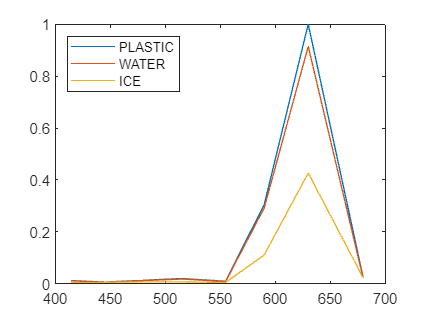

plot(AS_wavelengths, PLASTIC_RED{b,t}(1:8)./PLASTIC_RED{b,t}(7))
hold on
plot(AS_wavelengths, WATER_RED{b,t}(1:8)./PLASTIC_RED{b,t}(7))
plot(AS_wavelengths, ICE_RED{b,t}(1:8)./PLASTIC_RED{b,t}(7))
legend(medium_legend,'Location','northwest')
hold off

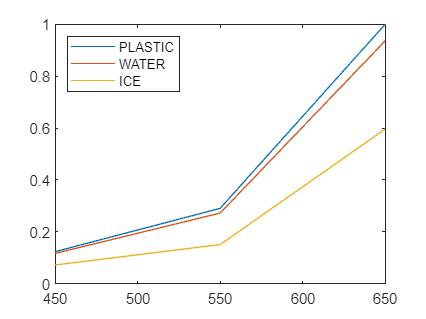


plot(VEML_wavelengths, PLASTIC_RED{b,t}(11:13)./PLASTIC_RED{b,t}(11))
hold on
plot(VEML_wavelengths, WATER_RED{b,t}(11:13)./PLASTIC_RED{b,t}(11))
plot(VEML_wavelengths, ICE_RED{b,t}(11:13)./PLASTIC_RED{b,t}(11))
legend(medium_legend,'Location','northwest')
hold off

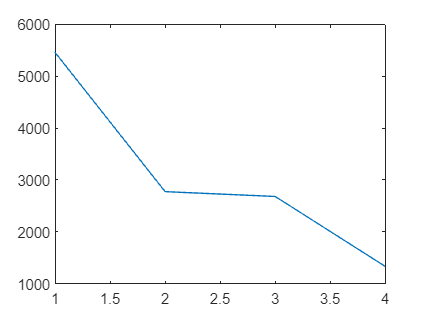


plot(1:4,[WHITE{b,1}(9),PLASTIC_WHITE{b,1}(9),WATER_WHITE{b,1}(9),ICE_WHITE{b,1}(9)])

% i = 1:9
% ratio = PLASTIC_WHITE{b,1}(i)./WHITE{b,1}(i)
% ratio = PLASTIC_RED{b,1}(i)./RED{b,1}(i)
% ratio = PLASTIC_GREEN{b,1}(i)./GREEN{b,1}(i)
% ratio = PLASTIC_BLUE{b,1}(i)./BLUE{b,1}(i)
% 
% j = 11:14
% ratio = PLASTIC_WHITE{b,1}(i)./WHITE{b,1}(i)
% ratio = PLASTIC_RED{b,1}(i)./RED{b,1}(i)
% ratio = PLASTIC_GREEN{b,1}(i)./GREEN{b,1}(i)
% ratio = PLASTIC_BLUE{b,1}(i)./BLUE{b,1}(i)

medium_plot('White',WHITE,PLASTIC_WHITE,WATER_WHITE,ICE_WHITE,[0.1,0.1,0.1], 7)

function medium_plot(colour, COLOUR, PLASTIC_COLOUR, WATER_COLOUR, ICE_COLOUR, RGB, j)
    AS = 1:8;
    VEML = 11:14;
    t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);
    AS_wavelengths = [415, 445, 480, 515, 555, 590, 630, 680];
    VEML_wavelengths = [650, 550, 450];
    direc = "MediumvsOutputFigures";
    for b = 1:10
        COLOUR_b = reshape(cell2mat(COLOUR(b,:)),15,6);
        PLASTIC_COLOUR_b = reshape(cell2mat(PLASTIC_COLOUR(b,:)),15,6);
        WATER_COLOUR_b = reshape(cell2mat(WATER_COLOUR(b,:)),15,6);
        ICE_COLOUR_b = reshape(cell2mat(ICE_COLOUR(b,:)),15,6);
        
        COLOUR_NORMAL_AS = COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
        PLASTIC_COLOUR_NORMAL_AS = PLASTIC_COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
        WATER_COLOUR_NORMAL_AS = WATER_COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
        ICE_COLOUR_NORMAL_AS = ICE_COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
    
        for t = 1:6
            % AS Plots[0 0 0.4 0.5]
            f = figure();
            plot(AS_wavelengths,COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB)
            hold on
            plot(AS_wavelengths,PLASTIC_COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB*3)
            plot(AS_wavelengths,WATER_COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB*5)
            plot(AS_wavelengths,ICE_COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB*7)

            grid on
            % xlabel("Integration Time (ms)",'FontSize',14);
            % ylabel("Counts",'FontSize',14)
            % plot_title = sprintf("AS7341 Channel Responses to %s Input Through Various Mediums",colour);
            % title(plot_title,'FontSize',18)
            % plot_subtitle = sprintf("brightness = %d%%, t_{int} = %d ms",b*10,t);
            % subtitle(plot_subtitle,'FontSize',12)
            % legend(AS_legend,'Location','northwest','NumColumns',2);
            
            % ax = gca;
            % ax.ColorOrder = AS_Colours;
            set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
            hold off
            filename = sprintf("%s/AS_%d_%s_%d_mediums.jpg",direc,b*10,colour,t_int(t));
            saveas(f,filename)
            close(f);
        end
    end
end

function condition_plot(colour, COLOUR, PLASTIC_COLOUR, WATER_COLOUR, ICE_COLOUR, RGB, j)
    AS = 1:8;
    VEML = 11:14;
    t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);
    AS_wavelengths = [415, 445, 480, 515, 555, 590, 630, 680];
    VEML_wavelengths = [650, 550, 450];
    direc = "MediumvsOutputFigures"
    for b = 1:10
        COLOUR_b = reshape(cell2mat(COLOUR(b,:)),15,6);
        PLASTIC_COLOUR_b = reshape(cell2mat(PLASTIC_COLOUR(b,:)),15,6);
        WATER_COLOUR_b = reshape(cell2mat(WATER_COLOUR(b,:)),15,6);
        ICE_COLOUR_b = reshape(cell2mat(ICE_COLOUR(b,:)),15,6);
        
        COLOUR_NORMAL_AS = COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
        PLASTIC_COLOUR_NORMAL_AS = PLASTIC_COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
        WATER_COLOUR_NORMAL_AS = WATER_COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
        ICE_COLOUR_NORMAL_AS = ICE_COLOUR_b(1:9,:)./PLASTIC_COLOUR_b(j,:);
    
        for t = 1:6
            % AS Plots
            f = figure();
            plot(AS_wavelengths,COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB)
            hold on
            plot(AS_wavelengths,PLASTIC_COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB*3)
            plot(AS_wavelengths,WATER_COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB*5)
            plot(AS_wavelengths,ICE_COLOUR_NORMAL_AS(AS,t), 'LineWidth',1.2, 'Color',RGB*7)

            grid on
            % xlabel("Integration Time (ms)",'FontSize',14);
            % ylabel("Counts",'FontSize',14)
            % plot_title = sprintf("AS7341 Channel Responses to %s Input Through Various Mediums",colour);
            % title(plot_title,'FontSize',18)
            % plot_subtitle = sprintf("brightness = %d%%, t_{int} = %d ms",b*10,t);
            % subtitle(plot_subtitle,'FontSize',12)
            % legend(AS_legend,'Location','northwest','NumColumns',2);
            
            % ax = gca;
            % ax.ColorOrder = AS_Colours;
            set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
            hold off
            filename = sprintf("%s/AS_%d_%s_%d_mediums.jpg",direc,b*10,colour,t_int(t));
            saveas(f,filename)
            close(f);
        end
    end
end
% function medium_plots(COLOUR, PLASTIC_COLOUR, WATER_COLOUR, ICE_COLOUR)
% plot(AS_wavelengths, COLOUR{5,1}(1:8))
% hold on
% plot(AS_wavelengths, WATER_COLOUR{5,1}(1:8))
% plot(AS_wavelengths, ICE_COLOUR{5,1}(1:8))
% legend("AIR","WATER","ICE")
% hold off
% end